close("all"); clear; clc;
setmadsympath();

speed = 110

speed = 110

root = "G:\My Drive\BikeSimResults\BigSports\Chicane\";
dir = root + "Vx" + speed + "Kph\";
ref = readtable(dir + "bikesim_results_"+ speed + "kph");

params = bigSportsParameters();
p = bikeSimToPrydeParameters(params,speed/3.6);

yaw = deg2rad(ref.Yaw);
pitch = deg2rad(ref.Pitch);
roll = deg2rad(ref.Roll_E);

R = angle2dcm(yaw,pitch,roll);
[yaw,camber,pitch] = dcm2angle(R,'ZXY');

steer = deg2rad(ref.Steer);

wx = deg2rad(ref.AVx);
wy = deg2rad(ref.AVy);
wz = deg2rad(ref.AVz);

vx = ref.Vxo./3.6;
vy = ref.Vyo./3.6;
vz = ref.Vzo./3.6;

wdx = ref.AAx;
wdy = ref.AAy;
wdz = ref.AAz;

ax = ref.Ax_SM;
ay = ref.Ay_SM;
az = ref.Az_SM;

x = [yaw,camber,pitch,steer,wx,wy,wz,vx,vy,vz];
u = [wdx,wdy,wdz,ax,ay,az];
params = [p.caster,1370E-03,speed/3.6];

addpath('steerObserver\');
A = stateMatrix(params);
B = inputMatrix(params);
C = outputMatrix();

sys = ss(A,B,eye(10),0);

t = ref.Time;
x_est = lsim(sys,u,t);
steer_est = x_est(:,4);

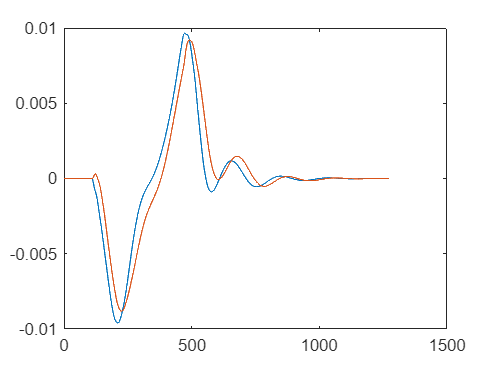

hold on
plot(steer)
plot(steer_est)
hold off
box on